# **变量、数组、矩阵及其运算和处理**

* 本节目标：

-         了解变量的命名规则及特殊变量

-         了解数组的创建、访问及运算

-         掌握矩阵的创建、访问及运算

# **1. 变量及其操作**

**1.1 命名规则**

**（1）变量名必须是不含空格的单个词；**

**（2）变量名区分大小写；**

**（3）变量名最多不超过31个字符，第31个字符之后的字符将被忽略；**

**（4）变量名必须以字母开头，之后可以是任意字母、数字或下划线，变量名中不允许使用标点符号. **

a = 1
A = 2

**1.2  一些特殊变量**

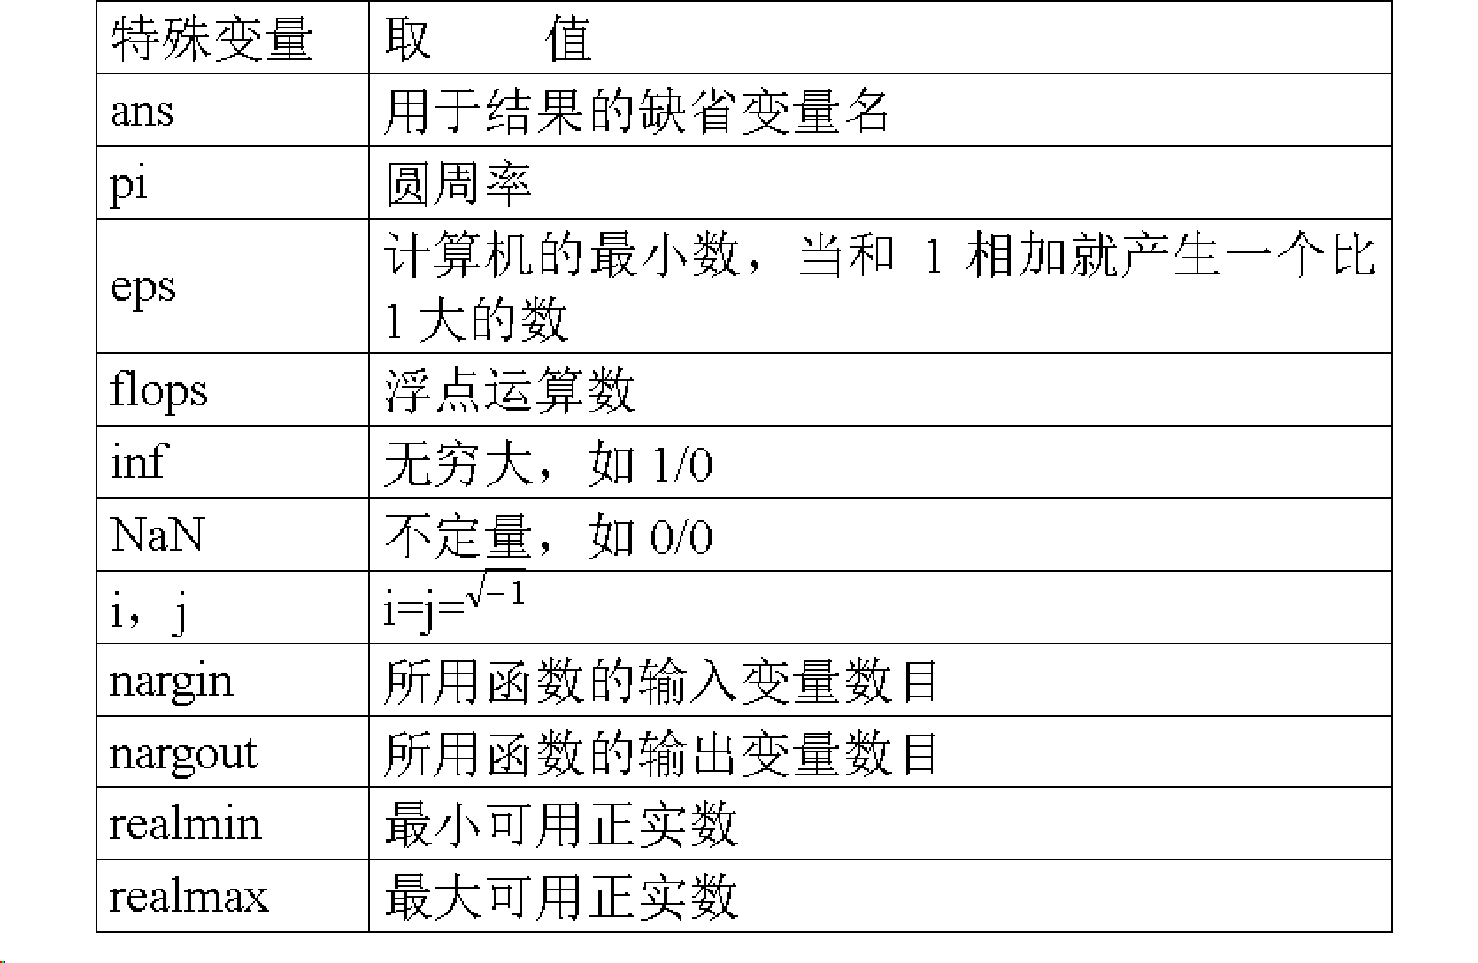

pi

**1.3 字符串（字符串的表示、操作）**

str1 = 'MATLAB'
str2 = 'MIkepp'
str1(2)
strA = [str1;str2]
strA(1,3)
strA(7)
% a = abs(str1)
% char(a+32)

# **2. 数组的创建、访问及方向**

**2.1 创建数组**

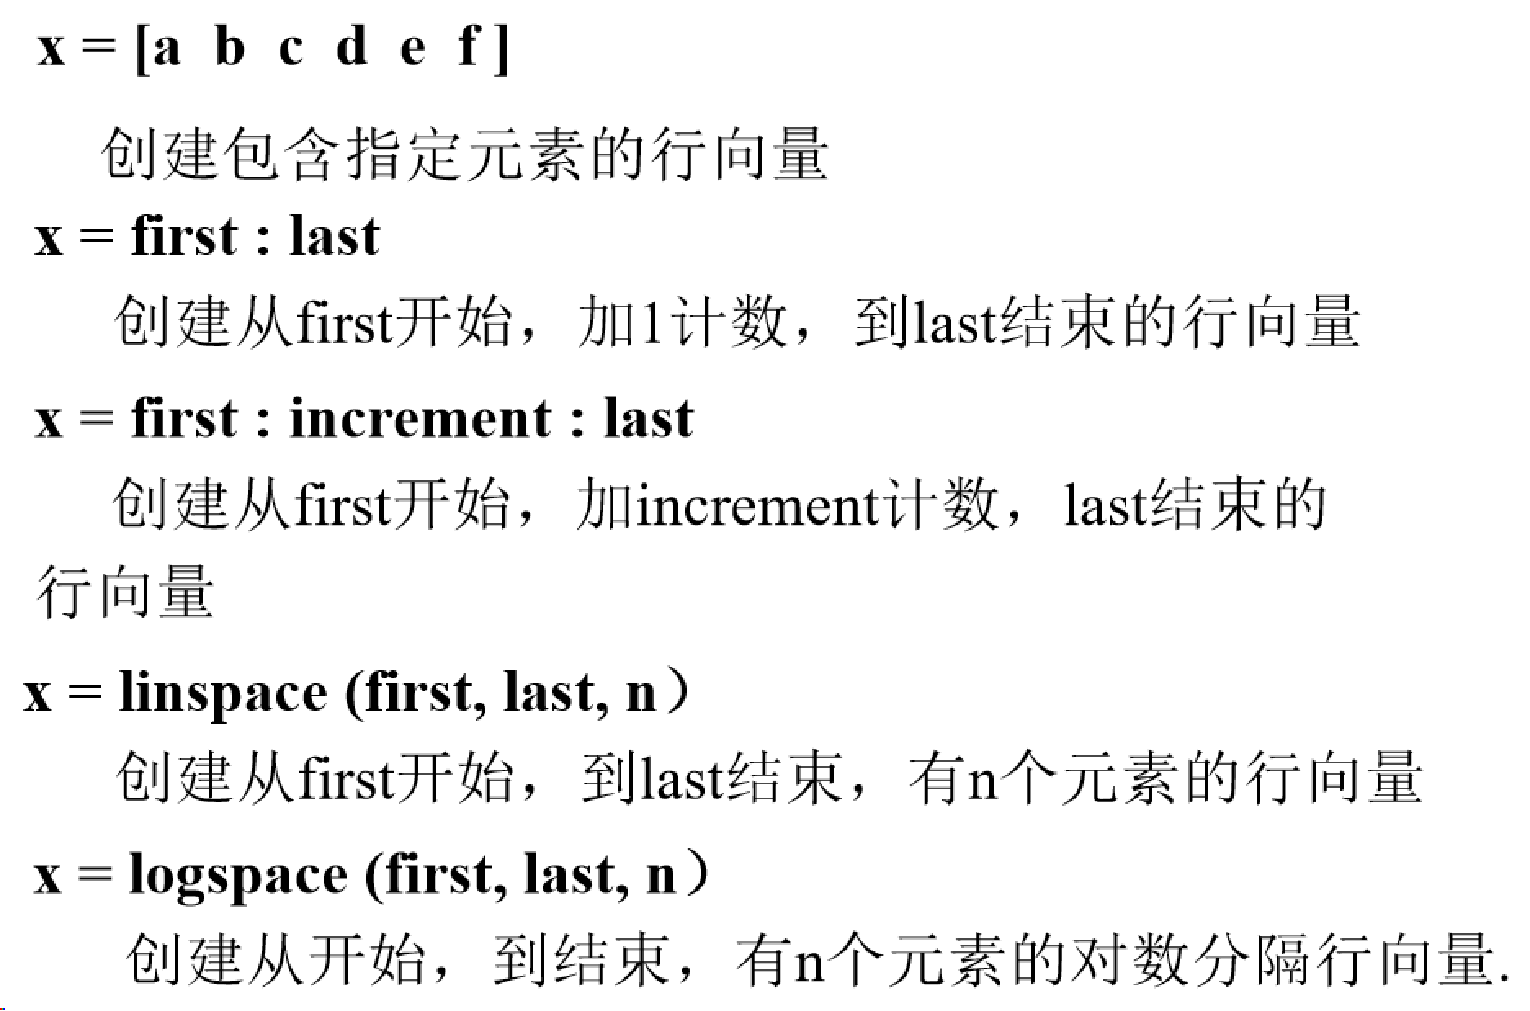

**2.2 访问数组**

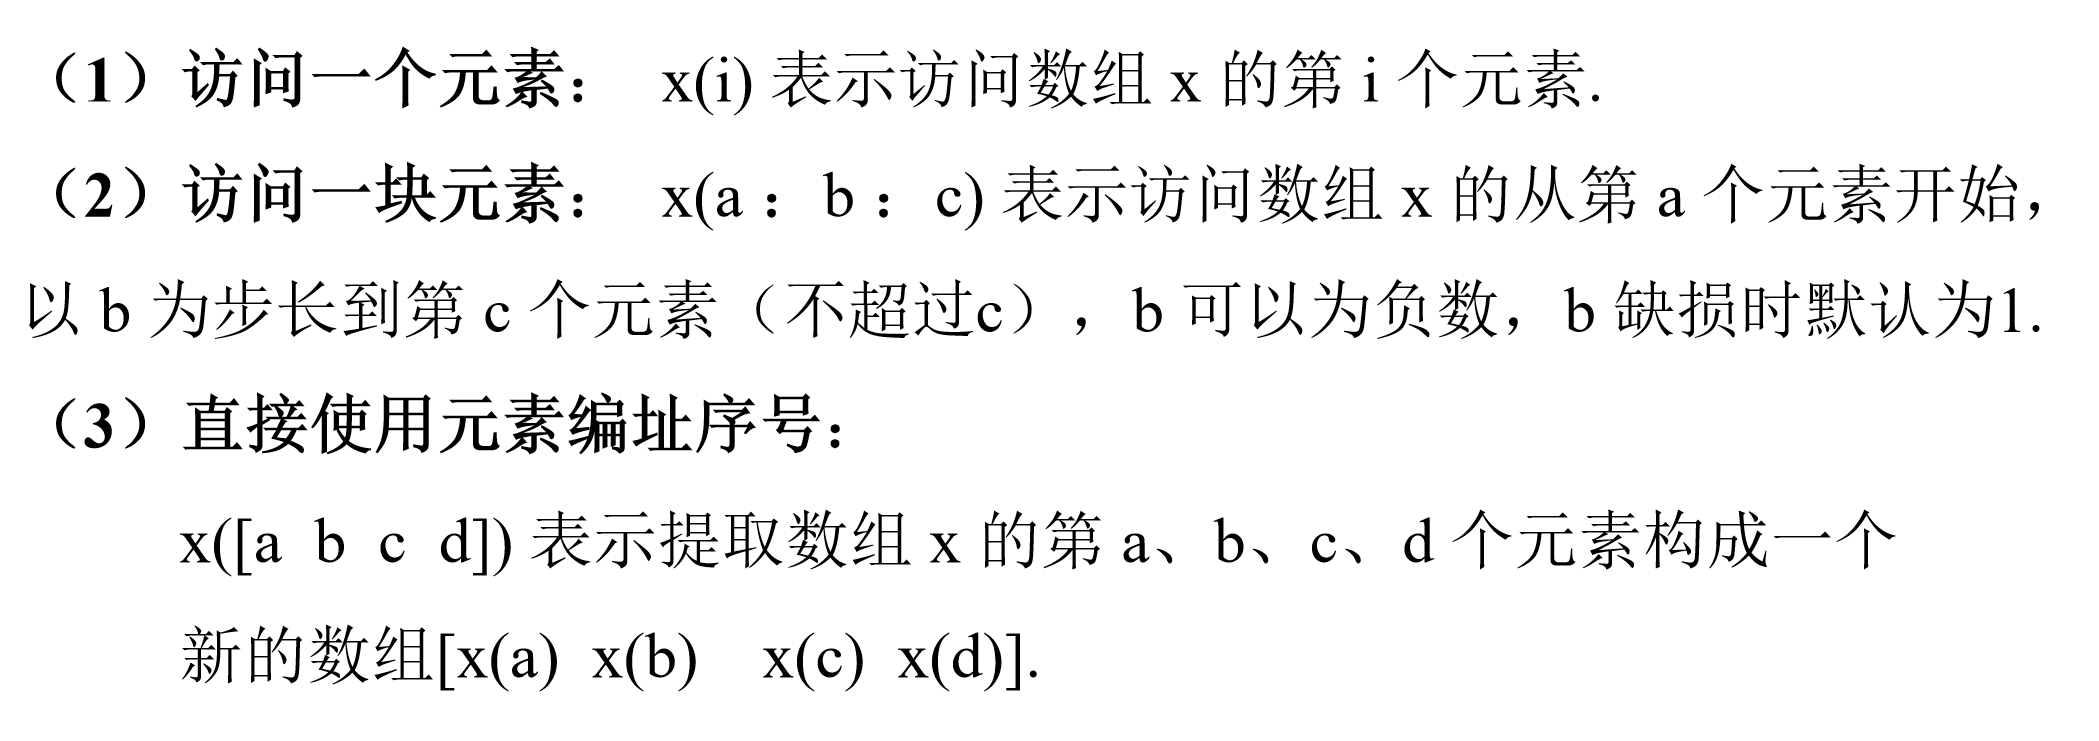

**2.3 数组的方向**

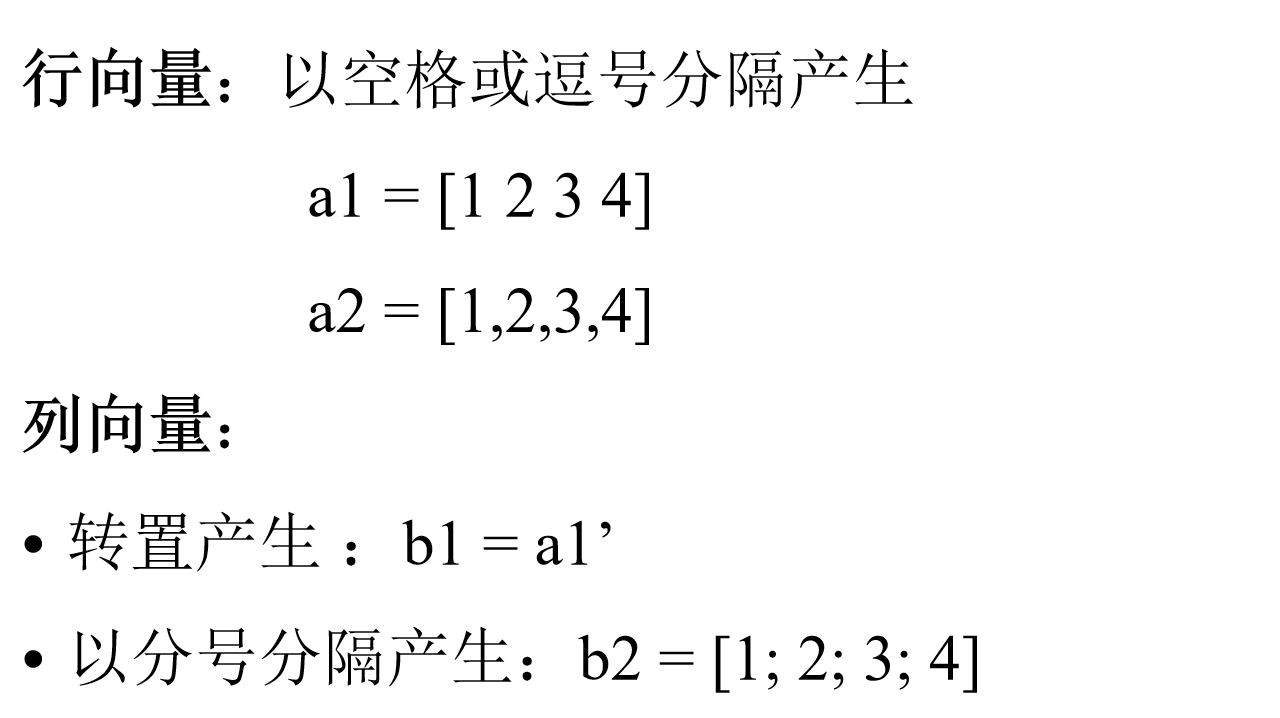

# **3. 矩阵操作**

## **            注：（各种数据类型都是以矩阵的形式存在的）👈**

**3.1 创建矩阵**

· 用逗号或空格用于分隔某一行的元素，分号用于区分不同的行. 

· 除了分号，在输入矩阵时，按Enter键也表示开始一新行. 

· 输入矩阵时，严格要求所有行有相同的列.    

%创建
A = [1 2 3 ;4, 5 ,6]
B = [5,6,8;9,0,4]
C = [A,B;B,A]
R = [1,2,3;4,5,6]
I = [8,0,9;4,6,1]
p=[1 1 1 1
2 2 2 2
3 3 3 3]

% 复数
com = R+I*1i

% 特殊矩阵
a=[ ]                    % 产生一个空矩阵，当对一项操作无结果时，返回空矩阵，	             空矩阵的大小为零. 
b=zeros(m,n)             % 产生一个m行、n列的零矩阵
c=ones(m,n)              % 产生一个m行、n列的元素全为1的矩阵
d=eye(m,n)               % 产生一个m行、n列的单位矩阵


**3.2 矩阵的元素处理**

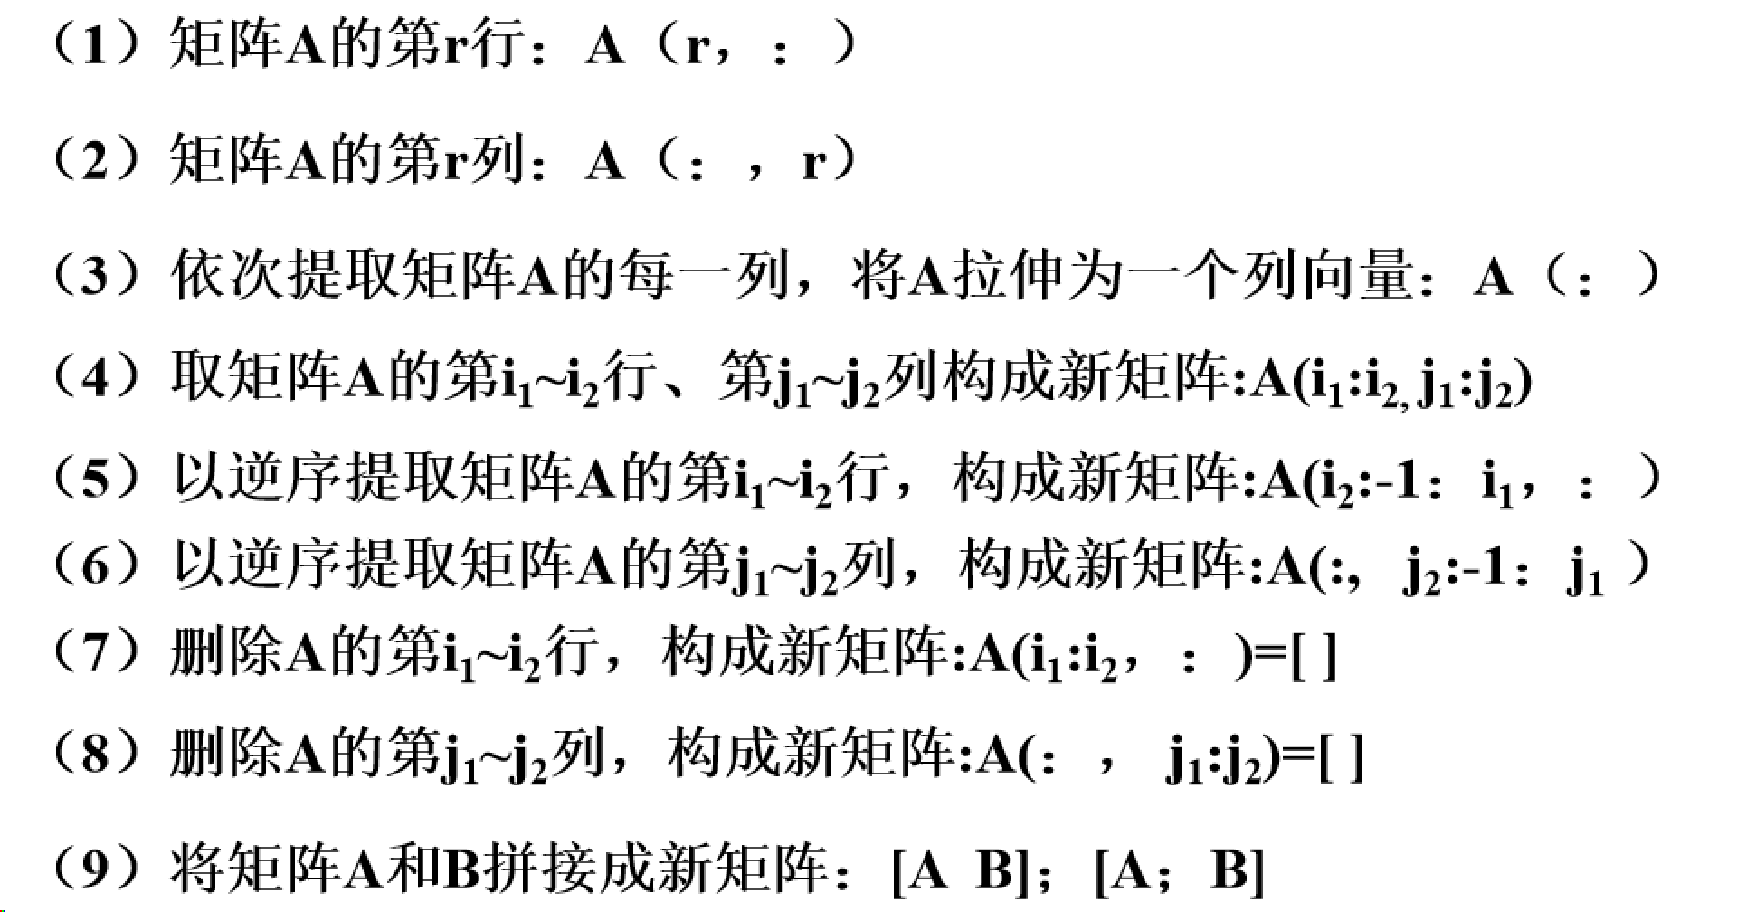

% 下标sub、 序号index
A(2,3)
A(7)
length(A)%6
ndims(A)%3
numel(A)%120
A(3,:)% : = all
A(:,2)
A(1:3,2:4)
A(:,1:3:5)

% reshape
F = [1 2 3 4 5 6 7 8 9 10 11 12]
F1 = reshape(F,4,3)% 从列开始排


**3.3 矩阵运算（算术、关系、逻辑）**

**（1）标量-矩阵运算**

**矩阵对标量的加、减、乘、除、乘方是矩阵的每个元素对该标量施加相应的加、减、乘、除、乘方运算. **

**（2）矩阵-矩阵运算**

**当两个矩阵有相同维数时，加、减、乘、除、幂运算可按元素对元素方式进行的，不同大小或维数的矩阵是不能进行运算的.**

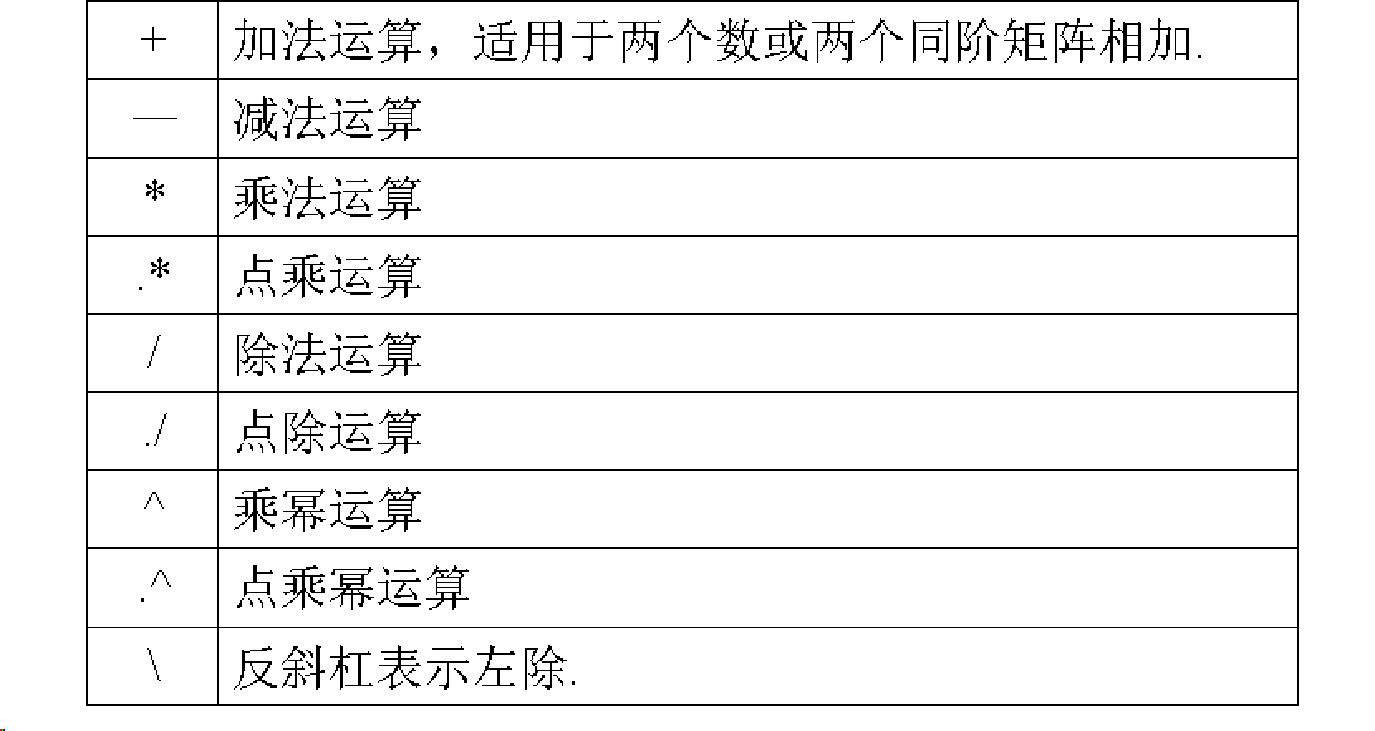   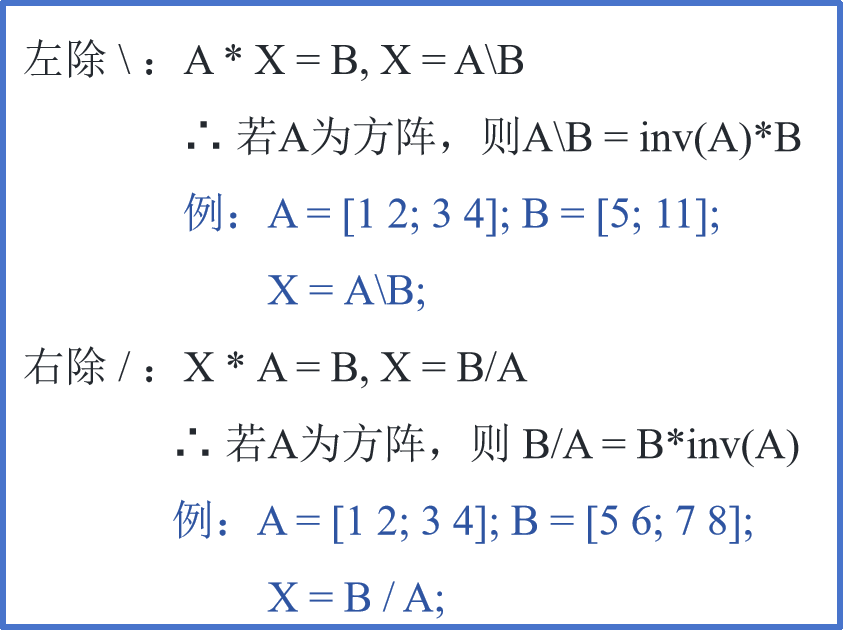

% 算数
% .* 
A=rand(3,3)
B=rand(3,3)
A.*B
%./  
A./B
% *   
A*B
% /
A/B

% 关系
% ==   %~=  

% 逻辑
%&  |   ~



# **4 矩阵处理**

### ** · 矩阵运算一直是一个复杂的问题 ·**

# **4.1 特殊矩阵**

**    -通用特殊矩阵**

% 零矩阵 1矩阵 单位矩阵
% zeros ones eye 
% rand：(0,1)之间均匀分布的随机数
% randn: (0,1)之间正态分布的随机数

% ex1
zeros(3)
zeros(3,4)
exA = ones(3,5)
zeros(size(exA))

% ex2 
% 建立[20,50]内均匀分布的5阶随机矩阵
% y = a + (b-a) x
exA1 = 20 +30*rand(5)

% ex3
eye(3,4)
eye(5,3)

% ex4 
% 产生一个均值为0.6，方差为0.1的4阶正态分布随机矩阵
% y = μ + σx
exA2 = 0.6 + sqrt(0.1)*randn(4)



**    -用于特殊领域的矩阵**

% 魔方矩阵 范德蒙矩阵 希尔伯特矩阵

% 魔方矩阵  n(n^2+1)/2
magic(3)
magic(4)

% 范德蒙矩阵   vander matrix 任意子方阵可逆
% | a1^0     ……     an^0     |
% | a1^1     ……     an^1     |
% | a1^(n-1) ……    an^(n-1)  |
V = [1,3,5,4,5]
vandermn = vander(V)
V1 = vandermn(3:5,1:3)
pinv(V1)

% 希尔伯特矩阵 高度病态 病态程度与阶数有关    hi,j = 1/(i + j -1)
format rat
H1 = hilb(4)
  

# **4.2 矩阵变换**

% 复习线代（一些名词的回忆，便于我们接下来能够连贯的掌握matlab的用法）

% 对角阵、数量矩阵、单位阵，秩、迹、逆(伪逆)、行列式、条件数 

% 范数（norm）：简单来说，用来度量某个向量空间（或矩阵）中的每个向量的长度或大小。

% 一些性质：转置运算对角线元素不变，矩阵的秩（rank）与方程组求解、判断是否可逆有关，矩
% 阵的迹（trace）为矩阵主对角线元素之和，相似变换时矩阵的迹不变。

**    -对角阵与三角阵**

% 构造对角阵
A = [5,4,1,0,9];
DA = diag(A) %1
DA1 = diag(A,1) %2
% 数量矩阵
B = eye(4)
DB = 7*B
% 取对角线元素
C = magic(4)
V1 = diag(C)
V1 = diag(C,1)
% ex1 建立一个5x5的矩阵A1，将A1的第一行元素乘1，第二行元素乘2，....，第五行元素乘5.
A1 = magic(5)
D1 = diag(1:5)
A1ans = D1*A1
% ex1 + 建立一个4x4的矩阵A2，将A2的第一列元素乘1，第二列元素乘2，....，第四列元素乘4.
A2 = magic(4)
D2 = diag(1:4)
A2ans = A2*D2

% 三角阵
% 上三角 (triu)
A3 = magic(7)
A3triup = triu(A3)
% 下三角 (tril)
A3tril = tril(A3)
% 小三角
A3triFra = triu(A3,2)  %第二个参数可负


**    -矩阵的转置与旋转**

% 转置
% m * n --> n * m
T = magic(4)
T1 = T.' 

% 共轭转置
R = magic(3)
I = magic(3).*3-7
T2 = R+I.*1i
T3 = T2'

% 旋转 rot90(A,K)   逆时针将A旋转k个90°
R1 = magic(4)
R1rot = rot90(R1,1)
R1rot = rot90(R1,4)

% 左右翻转
F = magic(3)
F1 = fliplr(F)

% 上下翻转
F2 = flipud(F)

**    -矩阵的逆与广义逆（伪逆）**

% 矩阵的逆：对于一个方阵A，如果存在一个与其同阶的方阵B，使得
%               A*B = B*A = I
% 则称B与A互为逆矩阵
% inv(A)


E = magic(3);
Einv = inv(E)
res = E*Einv 

% 求解线性方程组 Ax = b
% x = A^-1*b
% 
% ex2 求解下列方程组
% x+2y+3z=5
% x+4y+9z=-2
% x+8y+27z=6

A = [1 2 3;1 4 9;1 8 27]
b = [5;-2;6]
x = inv(A)*b

% 伪逆 pinv()
% 对于非方阵、奇异阵（是方阵，但行列式为0）
% 或非满秩矩阵（rank(A) ~= n ）


Aex2 = [3 1 1 1;1 3 1 1;1 1 3 1] 
rank(Aex2)  % 行满秩
A2ans = pinv(Aex2)
Aex2*A2ans

# **4.3 矩阵求值**

写在前面：  矩阵变换 矩阵 -> 矩阵

                    矩阵求值 矩阵 -> 数值

                    包括：行列式求值、矩阵的秩、矩阵的迹、范数、条件数 

**    -方阵的行列式 (de'terminant)**

% 注意 是方阵
% 函数 det(A)
A1 = rand (5)
A1res = det(A1)

**    -矩阵的秩与迹**

% 秩：非零子式的最高阶数  rank
%   秩的另一种解释：将矩阵按列分解为个向量，组成一个向量组。
%   则该向量组的一个最大线性无关组中包含向量的个数称为矩阵的行秩。同理可定义列秩，可证列秩=行秩=秩

%   -是否可逆
%   -初等变换后矩阵的秩不变
%   -判断非齐次线性方程组解的情况

% 迹: 矩阵主对角线元素的和   trace

% 矩阵的秩

A2 = magic(4)
A2res = rank(A2)

A3 = [2 2 -1 1;
      4 3 -1 2;
      8 5 -3 4;
      3 3 -2 2]
A3res = rank(A3)

% 矩阵的迹
A4 = magic(3)
A4res = trace(A4)

**    -向量和矩阵的范数**

% 向量或矩阵的范数用来度量其在某种意义下的长度。有多种定义，定义不同值也不同。
% 求范数时，注意要弄清楚是哪一种  

% 向量的范数
V = [1 2 3 4]
norm(V,1) % 向量-1 范数  元素绝对值之和
norm(V,2) % 向量-2 范数  元素平方和的平方根
norm(V,inf) % 向量-∞ 范数  所有向量元素绝对值中的最大值

% 矩阵的范数
E = magic(4)
norm(E,1) % 矩阵-1 范数  所有矩阵列元素绝对值之和的最大值
norm(E,2) % 矩阵-2 范数  矩阵的最大特征值的平方根
norm(E,inf) % 矩阵-∞ 范数  所有矩阵行元素绝对值之和的最大值


# **5 结构（structure)、单元（cell）**

**结构矩阵（struct）**

% % 结构矩阵的创建与操作
% clear
% % 定义一个 1x4 结构矩阵 
structA(1).ID = 0001;
structA(1).name = 'Mike';
structA(1).data = [30 50;80 90];

structA(2).ID = 0002;
structA(2).name = 'Kate';
structA(2).data = [50 30;90 10];



structA(3).ID = 0003;
structA(3).name = 'Amy';
    name.pet_name= 'sweet';
    name.used_name = 'White';
structA(3).data = [40 70;20 60];

structA(4).ID = 0004;
structA(4).name = 'John';
structA(4).data = [45 15;25 10];
structA(4).gender = 'Male';

structA


% 定义一个 2x2 结构矩阵
structB(1,1).ID = 0001;
structB(1,1).name = 'Mike';
structB(1,1).data = [30 50;80 90];

structB(1,2).ID = 0002;
structB(1,2).name = 'Kate';
structB(1,2).data = [50 30;90 10];



structB(2,1).ID = 0003;
structB(2,1).name = 'Amy';
    name.pet_name= 'sweet';
    name.used_name = 'White';
structB(2,1).data = [40 70;20 60];

structB(2,2).ID = 0004;
structB(2,2).name = 'John';
structB(2,2).data = [45 15;25 10];
structB(2,2).gender = 'Male';

structB

% % 结构矩阵的操作
% % 索引
structA(2).name
structA(3).name
name.pet_name
structA(4).data(3)

% % 修改
structA(4).name = 'John Little'
name.pet_name = 'alice'
structA(4).data(1,2) = 36

% %删除  rmfield
tempStruct = rmfield(structA,"gender")
structA(4).gender = []

**单元（元胞cell）**

% 元胞的创建与操作
% 与struct的区别 ： 元素没有自己的名字

% 创建
cellA = {1,'Mike',[10 20;30 40];
          2,'Kate',[90,85;60,13] ;
          3,'Amy',[77,89;50,4]}

% 索引 注意小括号和大括号的索引方式的不同之处！
cellA(2,3)
cellA{2,3}


% 向元胞元素中加入结构矩阵
strctCellA.data1 = 'testData1';
strctCellA.data2 = 'testData2';
strctCellA
cellA{3,4} = strctCellA 
cellA{1,4} = 'MATLAB is the greatest software'
cellA{2,4} = structA

% 显示整个元胞  celldisp cellplot
celldisp(cellA)
cellplot(cellA)

% 再次强调 { } 和 ( )的区别
cellA(4) = []